inputs

func = @(x) x.^2 - 4.*x + 4 - log(x)

func = function_handle with value:
    @(x)x.^2-4.*x+4-log(x)



p1 = 1

p1 = 1

p2 = 4

p2 = 4

max_iter = 100

max_iter = 100


% tolerance
tol = 1e-5

tol = 1.0000e-05

[root1, iter1, tab1] = newton_method_function(...
    p1, tol, max_iter, func ...
)

root1 = 1.4124

iter1 = 4

tab1 = 4×6 table
    iter      p0        p          f_p0        df_p0        f_p    
    ____    ______    ______    __________    _______    __________

     1           1    1.3333             1         -3       0.15676
     2      1.3333    1.4086       0.15676    -2.0833     0.0071969
     3      1.4086    1.4124     0.0071969    -1.8928    1.8094e-05
     4      1.4124    1.4124    1.8094e-05    -1.8833    1.1545e-10

	Get insights using Copilot


[root2, iter2, tab2] = newton_method_function( ...
    p2, tol, max_iter, func ...
)

root2 = 3.0571

iter2 = 5

tab2 = 5×6 table
    iter      p0        p          f_p0       df_p0        f_p    
    ____    ______    ______    __________    ______    __________

     1           4     3.303        2.6137      3.75       0.50301
     2       3.303    3.0846       0.50301    2.3033       0.04998
     3      3.0846    3.0575       0.04998    1.8451    0.00077258
     4      3.0575    3.0571    0.00077258     1.788    1.9669e-07
     5      3.0571    3.0571    1.9669e-07    1.7871     1.199e-14

	Get insights using Copilot


fprintf("root1 = %f; iteration = %d\nroot2 = %f; iteration = %d\n", ...
    root1, iter1, root2, iter2...
)

root1 = 1.412391; iteration = 4
root2 = 3.057104; iteration = 5


figure

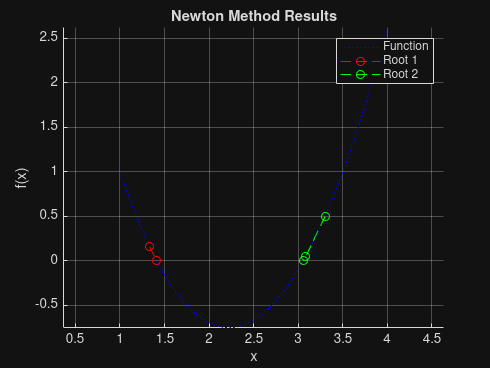

figure
hold on
fplot(func, [1, 4], 'b:')
plot(tab1.p, tab1.f_p, 'r--o')
plot(tab2.p, tab2.f_p, 'g--o')
grid on
xlabel('x');
ylabel('f(x)');
title('Newton Method Results');
legend('Function', 'Root 1', 'Root 2');
axis equal
hold off

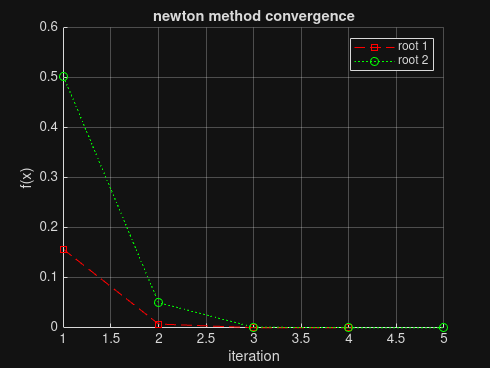

figure
hold on
plot(tab1.iter, tab1.f_p, 'r--s')
plot(tab2.iter, tab2.f_p, 'g:o')
grid on
xlabel("iteration")
ylabel("f(x)")
title("newton method convergence")
legend("root 1", "root 2")
% ylim([-0.01, 0.01])
hold off

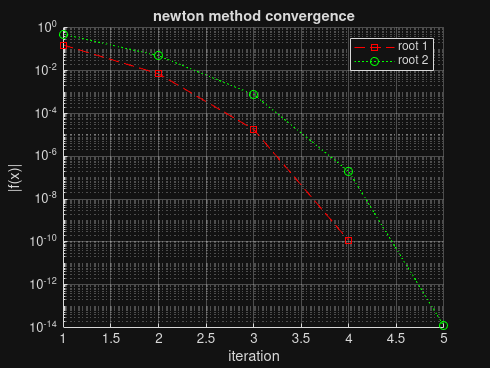

figure
hold on
plot(tab1.iter, abs(tab1.f_p), 'r--s')
plot(tab2.iter, abs(tab2.f_p), 'g:o')
grid on
xlabel("iteration")
ylabel("|f(x)|")
title("newton method convergence")
legend("root 1", "root 2")
set(gca, "YScale", "log")
hold off

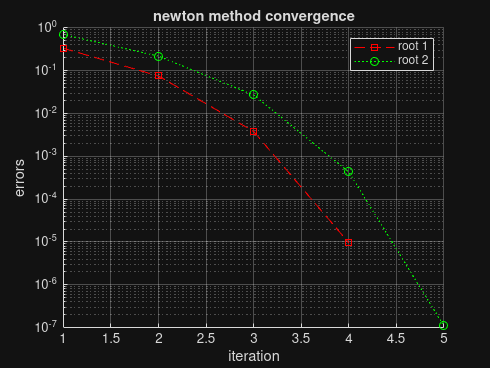

figure
hold on
plot(tab1.iter, abs(tab1.p - tab1.p0), 'r--s')
plot(tab2.iter, abs(tab2.p - tab2.p0), 'g:o')
grid on
xlabel("iteration")
ylabel("errors")
title("newton method convergence")
legend("root 1", "root 2")
set(gca, "YScale", "log")
hold off